## Assignment 3

Authors:

Kolja Westphal (455887) 

Thineth Gamage (456727)

Tristan de le Cruz Hachiles (405541)

% Class Objects
IT = InterplanetaryTransfers;
OP = OrbitPropagation;
warning('off','all')

## Task 1: Solving Lambert's Problem

Below we verify the correctness of the Lambert solver using the secant method with the given test-cases which match the results, for both cases.

### Test-Case A: Planetary Transfer Earth-Venus

% Constants Earth-Venus transfer
delta_theta_A  = deg2rad(75);           % rad
dt_A           = 180;                   % days
mu_A           = 398600.440;            % km³/s²
mu_converted_A = 0.00029591220828559;   % AU³/days²
rr_1_A         = [1 0 0]';              % AU
rr_2_A         = [0.187, 0.698, 0]';    % AU
factors_A      = [1, 2];                % [1]
max_iters      = 20;                    % [1]
tolerance_A    = 1E-8;                  % [1]

% Solve
[vv_1_A, vv_2_A, a_A] = IT.solve_lamberts_problem_secant(rr_1_A, rr_2_A, ... 
                                                         delta_theta_A, ...
                                                         dt_A, ...
                                                         mu_converted_A, ...
                                                         factors_A, ...
                                                         max_iters, ...
                                                         tolerance_A);
% Conversion factor from AU to km
AU_km   = 149597870.7;       % Km
day_s   = 1 * 24 * 60 * 60;  % s
fac_A   = AU_km / day_s;     % Km / s 

% Results of the Earth-Venus Transfer
disp("Velocities of Earth-Venus Transfers")

Velocities of Earth-Venus Transfers


vv_1_A = vv_1_A * fac_A     % Km / s

vv_1_A =    18.8368
   17.4054
         0


vv_2_A = vv_2_A * fac_A     % Km / s

vv_2_A =   -30.3940
  -20.3722
         0


### Test-Case B: Planetary Transfer Earth-Mars

% Inputs Case 2

delta_theta_B   = deg2rad(143.451);                                     % rad
dt_B            = 203 / 365.24219;                                      % Tropical years
mu_converted_B  = 4*pi^2;                                               % AU³/year²
rr_1_B          = [0.605774717586, -0.80374565571, 0.00010684714]';     % AU
rr_2_B          = [-0.01300489410, 1.575580535344, 0.033161980867]';    % AU
factors_B       = [1, 1.001];                                           % [1]
tolerance_B     = 1E-10;                                                % [1]

[vv_1_B, vv_2_B, a_B] = IT.solve_lamberts_problem_secant(rr_1_B, rr_2_B, ...
                                                        delta_theta_A, dt_B, ...
                                                        mu_converted_B, ...
                                                        factors_B, max_iters, tolerance_B);

% Results of the Earth-Mars Transfer
disp("Velocities of Earth-Mars Transfer:")

Velocities of Earth-Mars Transfer:


vv_1_B, vv_2_B % AU / year

vv_1_B =     1.4374
    3.3523
    0.1122


vv_2_B =    -2.0401
    2.1739
   -0.0117


## Task 2: Generating Porkchop Plots

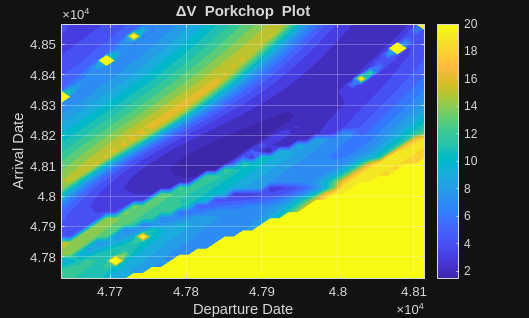

mu_converted = 39.4784176; %AU³/year²

% parse data files
[earth_data] = IT.parse_horizon_file('data/earth_data.txt', 'year');
[mars_data] = IT.parse_horizon_file('data/mars_data.txt', 'year');

% Create struct of lambet solver parameters
lsp.mu = mu_converted;
lsp.factors = [1, 2];
lsp.max_iterations = 20;
lsp.tolerance = 1E-8;

IT.create_porkchop_plot(lsp, earth_data, mars_data);

The porkchop plot shows the energetic feasibility of Earth–Mars transfers as a function of **departure date from Earth** and **arrival date at Mars**.

For each departure–arrival date combination, Lambert’s problem is solved using heliocentric ephemerides from the JPL Horizons system.

The color scale represents the transfer energy derived from the hyperbolic excess velocity obtained from the Lambert solution, while the diagonal structures indicate regions of approximately constant **time of flight**.

Low-energy regions correspond to favorable launch windows with reduced transfer energy requirements. In this case these areas are found in the middle of the porkchopplot

The plot covers departure dates from **June 2030 to September 2031** and arrival dates from **September 2030 to January 2033**, allowing suitable Earth–Mars transfer opportunities to be identified within this timeframe.

The Code is Explained in InterplanetaryTransfers.m

## Task 3: Patched-Conics Trajectory

### I. Hyperbolic departure orbit from Earth with minimum C3 

Constants required for Earth and Mars

% ---- Unit conversion: AU/year -> km/s ----
AU2km   = 1.495978707e8;                 % km
yr2s    = 365.24219*24*3600;             % s

% converted mu of the sun 
mu_sun   = 4*pi^2;        % AU^3 / year^2

% Periapsis altitude for both Mars and Earth (200 km)
hp = 1.34e-6;             % AU

% Lambert Solver parameters
lsp.mu              = mu_sun;
lsp.factors         = [1, 1.001];
lsp.max_iterations  = 20;
lsp.tolerance       = 1E-8;

% parse data files
[earth_data] = IT.parse_horizon_file('data/earth_data.txt', 'year'); % AU
[mars_data]  = IT.parse_horizon_file('data/mars_data.txt', 'year');   % AU

Compute all possible transfer combinations and find Ephemerides from the lowest Earth departure v_inf .

% Gravitational parameters
mu_earth = 1.1857e-4;     % AU^3 / year^2
% Radii of Earth
Re = 4.26e-5;             % AU

% Minimum solution for departure
[vv_inf_A, ephem_depA, ephem_arrA, dThetaA, dT_A] = IT.minimum_vinf_vals(...
    lsp, earth_data, mars_data, true);

% Plot Departure hyperbolic orbit
rrEarth_A = ephem_depA(1,2).Position; % AU
rrMars_A = ephem_arrA(1,2).Position;  % AU
vvEarth_A = ephem_depA(1,3).Velocity; % AU / Year
vvMars_A = ephem_arrA(1,3).Velocity;  % AU / Year

% Solve Lambert's problem for minimum departure C3
[vv1_A, vv2_A, ~] = IT.solve_lamberts_problem_secant(rrEarth_A, rrMars_A, dThetaA, dT_A, mu_sun, ...
                                lsp.factors, lsp.max_iterations, lsp.tolerance);

Use the Lambert solution to derive the hyperbolic orbit

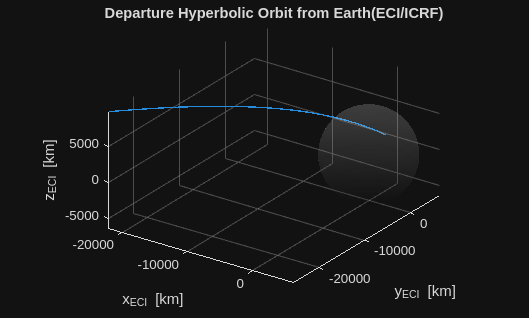

% Find position and velocity vector at hyperbolic perigee for orbit
% propagation
rEarth_p        = Re + hp; 
crossA          = cross(rrEarth_A, vv1_A);    
hA              = crossA / norm(crossA);        % normalize
vv_inf_earth    = vv1_A - vvEarth_A;      
v_EarthPerigee  = sqrt(norm(vv_inf_earth)^2 + (2 * mu_earth) / rEarth_p); % Magnitude NOT VECTOR
e_earth         = 1 + (rEarth_p * norm(vv_inf_earth)^2) / mu_earth;
deltaA          = asin(1 / e_earth) * 2;

% Rotate vv_inf_earth to get perigee tangential velocity. Position vector
% results from the cross product between impulse and velocity
vv_perigee_earth_norm   = IT.rotateVector(vv_inf_earth, hA, -deltaA / 2) / norm(vv_inf_earth);
vv_perigee_earth        = vv_perigee_earth_norm * v_EarthPerigee;
rr_perigee_earth_norm   = cross(vv_perigee_earth_norm, hA) / norm(cross(vv_perigee_earth_norm, hA));
rr_perigee_earth        = rr_perigee_earth_norm * rEarth_p;

% Extract Kepler Elements and convert from AU / year -> km / s
[aE, eE, iE, RAANE, omegaE, nuE] = OP.convert_car2kep(rr_perigee_earth, vv_perigee_earth, mu_earth);

% Lengths Earth 
aE       = aE * AU2km;                   % km
Re       = Re * AU2km;                   % km
rr_perigee_earth = rr_perigee_earth * AU2km;           % km
% Velocities Earth 
vv_perigee_earh = vv_perigee_earth * AU2km / yr2s;    % km/s
% Time
t1 = 90 * 60; % s
t_step = 60;  % s
mu_earth_converted = 398600;    % km^3/s^2

% Propagate and Plot Earth hyperbolic departure
[ttE, Rearth, Vearth, nunuEarth, OMOMEarth] = OP.propagate_orbit_keplar_newton(aE, eE, iE, RAANE, omegaE, nuE, ...
                            mu_earth_converted, 0, t1, t_step, 0 , 0, true);


figure('Name','Minimum C3 Departure 3D Orbit (ECI)');
plot3(Rearth(:,1), Rearth(:,2), Rearth(:,3), 'LineWidth', 1.0); hold on; grid on; axis equal;
[fX,fY,fZ] = sphere(80);
surf(Re*fX, Re*fY, Re*fZ, 'FaceAlpha', 0.1, 'EdgeColor', 'none'); colormap gray;
xlabel('x_{ECI} [km]'); ylabel('y_{ECI} [km]'); zlabel('z_{ECI} [km]');
title('Departure Hyperbolic Orbit from Earth(ECI/ICRF)');
view(35,25);

Plot helliocentric elliptical Earth departure orbit with minimum C3. We use the resulting departure velocity from the lambert solver  and the Ephemerides. With this the orbit is complete 

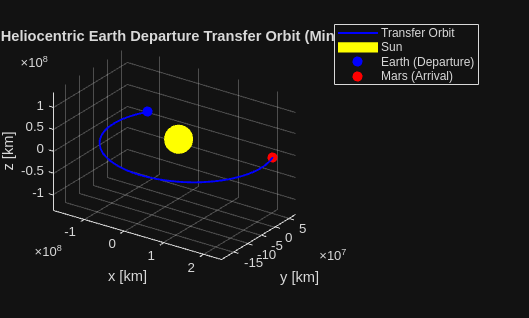

% ================= HELIOCENTRIC TRANSFER ORBIT EARTH DEPARTURE =================

% ---- Constants ----
mu_sun_converted = 1.32712440018e11;  % km^3/s^2

% ---- Convert Lambert state to Kepler elements (Sun-centered) ----
[aTA, eTA, iTA, RAANTA, omegaTA, nuTA] = ...
    OP.convert_car2kep(rrEarth_A, vv1_A, mu_sun);

% ---- Unit conversion AU/year -> km/s ----
aTA          = aTA * AU2km;
rrTA_Earth   = rrEarth_A * AU2km;
rrTA_Mars    = rrMars_A  * AU2km;
vvTA_dep     = vv1_A * AU2km / yr2s;

%% ---- Propagation time ----

tTA_end  = dT_A * yr2s;        % seconds
tT_step = 24*3600;            % 1 day

%% ---- Propagate heliocentric elliptic transfer orbit ----
[~, R_TA, ~, ~, ~] = ...
    OP.propagate_orbit_keplar_newton( ...
        aTA, eTA, iTA, RAANTA, omegaTA, nuTA, ...
        mu_sun_converted, ...
        0, tTA_end, tT_step, 0, 0, false);

% ===================== PLOTTING =====================

figure('Name','Heliocentric Transfer Orbit');
hold on; grid on; axis equal;

% ---- Plot transfer orbit ----
plot3(R_TA(:,1), R_TA(:,2), R_TA(:,3), ...
      'b', 'LineWidth', 1.4);

% ---- Plot Sun ----
[fX,fY,fZ] = sphere(50);
surf(0.2*AU2km*fX, 0.2*AU2km*fY, 0.2*AU2km*fZ, ...
     'FaceColor','y','EdgeColor','none');

% ---- Plot Earth at departure ----
plot3(rrTA_Earth(1), rrTA_Earth(2), rrTA_Earth(3), ...
      'bo', 'MarkerFaceColor','b', 'MarkerSize',7);

% ---- Plot Mars at arrival ----
plot3(rrTA_Mars(1), rrTA_Mars(2), rrTA_Mars(3), ...
      'ro', 'MarkerFaceColor','r', 'MarkerSize',7);

% ---- Labels ----
xlabel('x [km]');
ylabel('y [km]');
zlabel('z [km]');
title('Elliptic Heliocentric Earth Departure Transfer Orbit (Minimum C3)');
view(35,25);

legend('Transfer Orbit','Sun','Earth (Departure)','Mars (Arrival)');

### II. Hyperbolic arrival orbit to Mars with minimum v_inf 

Essentially the same as the departure, but for this we need to get the minimum solution for the arrival first 

% Gravitational parameters
mu_mars  = 3.227e-5;      % AU^3 / year^2
% Radii of Planet
Rm = 2.27e-5;             % AU

% Minimum solution for departure
[vv_inf_B, ephem_depB, ephem_arrB, dThetaB, dT_B] = IT.minimum_vinf_vals(...
    lsp, earth_data, mars_data, false); 

% Plot Departure hyperbolic orbit
rrEarth_B   = ephem_depB(1,2).Position;  % AU
rrMars_B    = ephem_arrB(1,2).Position;  % AU
vvEarth_B   = ephem_depB(1,3).Velocity;  % AU / Year
vvMars_B    = ephem_arrB(1,3).Velocity;  % AU / Year

% Solve Lambert's problem for minimum arrival v_inf 
[vv1_B, vv2_B, ~] = IT.solve_lamberts_problem_secant(rrEarth_B, rrMars_B, dThetaB, dT_B, mu_sun, ...
                                lsp.factors, lsp.max_iterations, lsp.tolerance);

Use the Lambert solution to derive the hyperbolic arrival orbit 

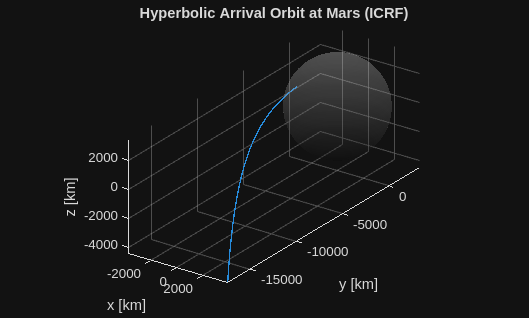

% Find position and velocity vector at hyperbolic perigee for orbit propagation (Mars)
rMars_p        = Rm + hp;
crossB         = cross(rrMars_B, vv2_B); 
hB             = crossB / norm(crossB);          % normalize angular momentum direction

vv_inf_mars    = vv2_B - vvMars_B;      
v_MarsPerigee  = sqrt(norm(vv_inf_mars)^2 + (2 * mu_mars) / rMars_p); % Magnitude ONLY

e_mars         = 1 + (rMars_p * norm(vv_inf_mars)^2) / mu_mars;
deltaB         = 2 * asin(1 / e_mars);

% Rotate v_inf to get perigee tangential velocity (Mars)
vv_perigee_mars_norm = ...
    IT.rotateVector(vv_inf_mars, hB,  deltaB / 2) / norm(vv_inf_mars);

vv_perigee_mars      = vv_perigee_mars_norm * v_MarsPerigee;

% Perigee position vector (normal to velocity & angular momentum)
rr_perigee_mars_norm = ...
    cross(vv_perigee_mars_norm, hB) / norm(cross(vv_perigee_mars_norm, hB));

rr_perigee_mars      = rr_perigee_mars_norm * rMars_p;

% Extract Keplerian elements (AU / yr)
[aM, eM, iM, RAANM, omegaM, nuM] = ...
    OP.convert_car2kep(rr_perigee_mars, vv_perigee_mars, mu_mars);

% =============================
% Unit conversion AU/yr → km/s
% =============================

% Lengths Mars
aM               = aM * AU2km;                 % km
Rm               = Rm * AU2km;                 % km
rr_perigee_mars  = rr_perigee_mars * AU2km;    % km

% Velocities Mars
vv_perigee_mars  = vv_perigee_mars * AU2km / yr2s; % km/s

% Time
t1     = 90 * 60;   % s
t_step = 60;        % s

% Mars gravitational parameter
mu_mars_converted = 42828;    % km^3/s^2

% Propagate and plot Mars hyperbolic arrival
[ttM, Rmars, Vmars, nunuMars, OMOMMars] = ...
    OP.propagate_orbit_keplar_newton( ...
        aM, eM, iM, RAANM, omegaM, nuM, ...
        mu_mars_converted, 0, t1, t_step, 0, 0, true);

figure('Name','Minimum C3 Arrival 3D Orbit (Mars)');
plot3(Rmars(:,1), Rmars(:,2), Rmars(:,3), 'LineWidth', 1.0); 
hold on; grid on; axis equal;

% Draw translucent Mars
[fX,fY,fZ] = sphere(80);
surf(Rm*fX, Rm*fY, Rm*fZ, ...
    'FaceAlpha', 0.15, 'EdgeColor', 'none'); 
colormap gray;

xlabel('x [km]'); ylabel('y [km]'); zlabel('z [km]');
title('Hyperbolic Arrival Orbit at Mars (ICRF)');
view(35,25);

Finally we can also propagate and plot the elliptical transfer orbit for the minimum arrival velocity 

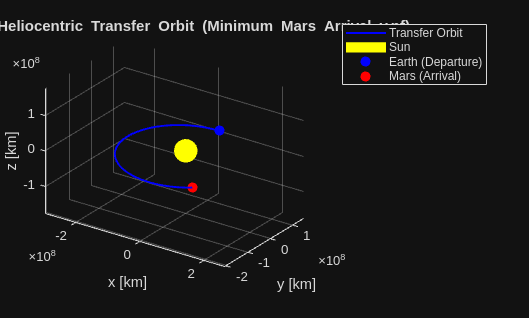

%% ================= HELIOCENTRIC TRANSFER ORBIT MARS ARRIVAL =================

% ---- Convert Lambert state to Kepler elements (Sun-centered) ----
[aTB, eTB, iTB, RAANTB, omegaTB, nuTB] = ...
    OP.convert_car2kep(rrEarth_B, vv1_B, mu_sun);

% ---- Unit conversion AU/year -> km/s ----
aTB          = aTB * AU2km;
rrTB_Earth   = rrEarth_B * AU2km;
rrTB_Mars    = rrMars_B  * AU2km;
vvTB_arr     = vv1_B * AU2km / yr2s;

%% ---- Propagation time ----
tTB_end  = dT_B * yr2s;        % seconds


%% ---- Propagate heliocentric elliptic transfer orbit ----
[~, R_TB,~, ~, ~] = ...
    OP.propagate_orbit_keplar_newton( ...
        aTB, eTB, iTB, RAANTB, omegaTB, nuTB, ...
        mu_sun_converted, ...
        0, tTB_end, tT_step, 0, 0, false);

% ===================== PLOTTING =====================

figure('Name','Heliocentric Transfer Orbit Mars Arrival');
hold on; grid on; axis equal;

% ---- Plot transfer orbit ----
plot3(R_TB(:,1), R_TB(:,2), R_TB(:,3), ...
      'b', 'LineWidth', 1.4);

% ---- Plot Sun ----
[fX,fY,fZ] = sphere(50);
surf(0.2*AU2km*fX, 0.2*AU2km*fY, 0.2*AU2km*fZ, ...
     'FaceColor','y','EdgeColor','none');

% ---- Plot Earth at departure ----
plot3(rrTB_Earth(1), rrTB_Earth(2), rrTB_Earth(3), ...
      'bo', 'MarkerFaceColor','b', 'MarkerSize',7);

% ---- Plot Mars at arrival ----
plot3(rrTB_Mars(1), rrTB_Mars(2), rrTB_Mars(3), ...
      'ro', 'MarkerFaceColor','r', 'MarkerSize',7);

% ---- Labels ----
xlabel('x [km]');
ylabel('y [km]');
zlabel('z [km]');
title('Elliptic Heliocentric Transfer Orbit (Minimum Mars Arrival v_inf)');
view(35,25);

legend('Transfer Orbit','Sun','Earth (Departure)','Mars (Arrival)');